**Read all instructions carefully!**

**Instructions on what to turn in: **

Download the folder lab4files to your machine. Inside you will find the following files: 

- lab4_lastname.mlx (rename this file to include your last name)

What you will need to turn in on Canvas. Upload the following 2 files:

- lab4_lastname.pdf  (instructions on how to generate this below)

- lab4_lastname.mlx

How to generate lab4_lastname.pdf. 

Once you have completed all the parts of the assignment and are satisfied with your work, go View in the top bar and click Output Inline - this makes it so that the grader can easily follow your work. Run lab4_lastname.mlx one more time then go to Live Editor and click Export then choose PDF. A pdf file with the same name as the Live script will be generated with answers to all the parts. 

**Specific instructions for the assignment:**

- In Problem 2 you will create a Matlab function within a script. Any Matlab functions defined within a script (Live or otherwise) should appear at the very end of the script. Any calls to that functions will be above the function. 

- To make your work easy to grade, please suppress all outputs except for the parts that explictly say not to suppress output. This is most important for any Matlab functions you develop! Please make sure everything runs.  

**Problem 1**

format long % shows output with more digits

**a)** Plot the function $f(x) = \frac{1}{1+12x^2}$ on $[-1,1]$ using 100 evenly spaced points. 

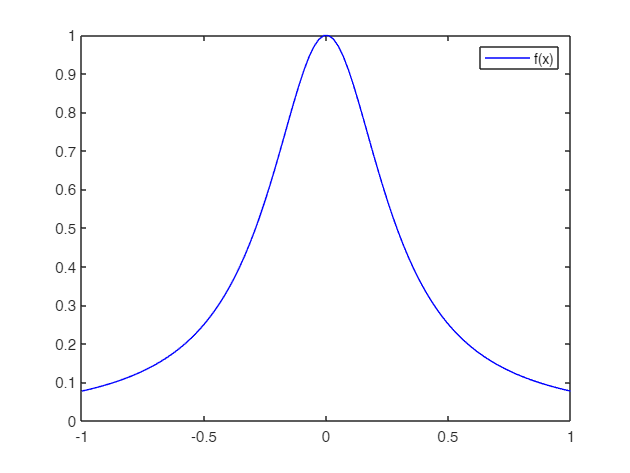

f = @(x) 1./(1+(12*x.^2));
x = linspace(-1, 1, 100);

plot(x, f(x), 'b');
legend("f(x)");

**b)** Use Lagrange Interpolation to approximate the function $f(x) = \frac{1}{1+12x^2}$ using the nodes $x_0 = -1, x_1 = 0, x_2 = 1$. Define$L_0(x), \quad  L_1(x) , \quad  L_2(x)$ then compute $P_2(x) = \sum_{k=0}^2 f(x_k)L_k(x)$. Use anonymous functions.

x0 = -1;
x1 = 0;
x2 = 1;

L0 = @(x) ( (x-x1).*(x-x2)  ) / ( (x0-x1).*(x0-x2) );
L1 = @(x) ( (x-x0).*(x-x2)  ) / ( (x1-x0).*(x1-x2) );
L3 = @(x) ( (x-x0).*(x-x1)  ) / ( (x2-x0).*(x2-x1) );

P2 = @(x) (L0(x) * f(x0)) + (L1(x) * f(x1)) + (L3(x) * f(x2));

**c)** Plot $P_2(x)$ on the same figure with $f(x)$ using 100 evenly spaced points. Use different colors for the plots.

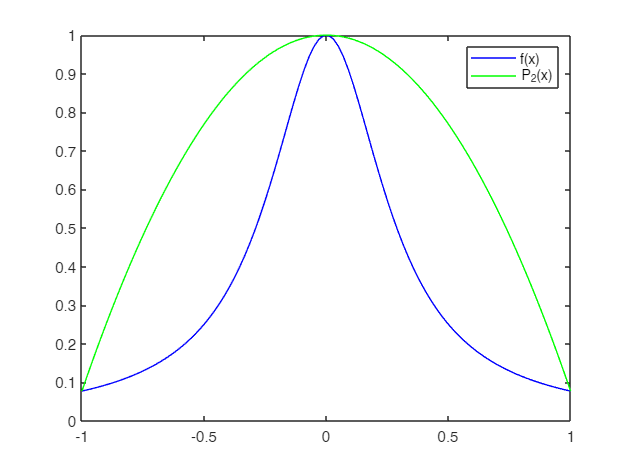

plot(x, f(x), 'b', x, P2(x), 'g');
legend("f(x)", "P_2(x)");

**d)** Use Lagrange interpolation to approximate the same function using the nodes $\{-1,-0.5,0,0.5,1\}$. Define the required basis functions $L_k(x)$ then compute $P_4(x)$. Use anonymous functions. 

x0 = -1;
x1 = -0.5;
x2 = 0;
x3 = 0.5;
x4 = 1;

L0 = @(x) ( (x-x1).*(x-x2).*(x-x3).*(x-x4)  ) / ( (x0-x1).*(x0-x2).*(x0-x3).*(x0-x4) );
L1 = @(x) ( (x-x0).*(x-x2).*(x-x3).*(x-x4)  ) / ( (x1-x0).*(x1-x2).*(x1-x3).*(x1-x4) );
L2 = @(x) ( (x-x0).*(x-x1).*(x-x3).*(x-x4)  ) / ( (x2-x0).*(x2-x1).*(x2-x3).*(x2-x4) );
L3 = @(x) ( (x-x0).*(x-x1).*(x-x2).*(x-x4)  ) / ( (x3-x0).*(x3-x1).*(x3-x2).*(x3-x4) );
L4 = @(x) ( (x-x0).*(x-x1).*(x-x2).*(x-x3)  ) / ( (x4-x0).*(x4-x1).*(x4-x2).*(x4-x3) );

P4 = @(x) (L0(x) * f(x0)) + (L1(x) * f(x1)) + (L2(x) * f(x2)) + (L3(x) * f(x3)) + (L4(x) * f(x4));


**e) **Plot $P_4(x)$ on the same figure with $f(x)$ and $P_2(x)$ using 100 evenly spaced points. Use different colors for the plots. Add a legend. 

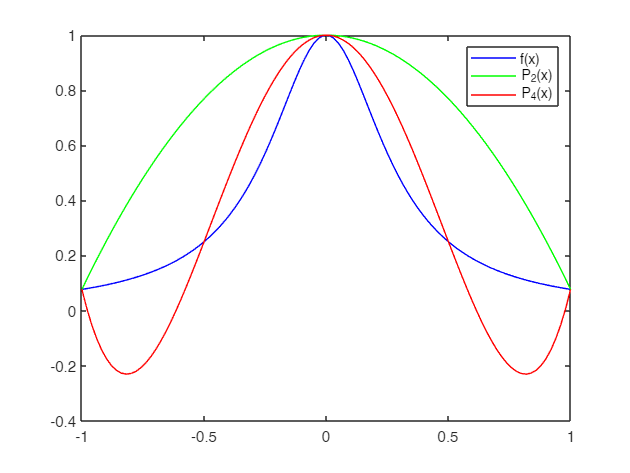

% hold on;
plot(x, f(x), 'b', x, P2(x), 'g', x, P4(x), 'r');
legend("f(x)", "P_2(x)", "P_4(x)");

**f)**  Compute the absolute errors when $P_2$ and $P_4$ are used to approximate $f(0.45)$. *(Do not suppress output)*

diff = abs(P4(0.45) - P2(0.45));
sprintf("The absolute difference is %s", diff)

ans = "The absolute difference is 4.472135e-01"

**Problem 2: **

***Work on part b) before part a)!***

**a)** Test your function $\texttt{newttd}$ developed below using data from Table 3.10 in Burden, Faires, and Burden. i.e. create two vectors : one containing the values of $x$ and another containing the values of $f(x)$. Then use these vectors as inputs to $\texttt{newtdd}$. *(Do not suppress output from your function call).*

*The values in your output matrix should match the values in the Table 3.11 - from column 3 onwards.*

**b)** Create a Matlab function that implements Algorithm 3.2 from Burden,Faires, Burden below. Adjust the indexing from the pseudocode to match Matlab indexing. 

Copy and paste the following starter code into the grey box below and complete your function : 

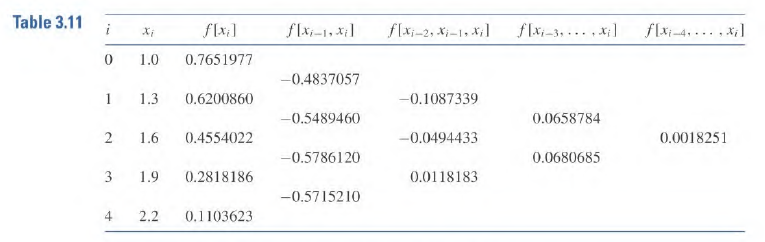

%X = [-1, -0.5, 0, 0.5, 1];
%Y = arrayfun(f, X);

X = [1.0, 1.3, 1.6, 1.9, 2.2];
Y = [0.7651977, 0.6200860, 0.4554022, 0.2818186, 0.1103623];


F = newtdd(X, Y)

F =    0.765197700000000                   0                   0                   0                   0
   0.620086000000000  -0.483705666666666                   0                   0                   0
   0.455402200000000  -0.548946000000000  -0.108733888888889                   0                   0
   0.281818600000000  -0.578612000000000  -0.049443333333334   0.065878395061728                   0
   0.110362300000000  -0.571520999999999   0.011818333333335   0.068068518518521   0.001825102880660


function F = newtdd(x,y)
% Implements Newton's Divided Differences formula for interpolation
% Inputs: x - vector of interpolation nodes 
%         y - vector of function values at the nodes 

N = length(x);
F = zeros(N);

%generate first column -> f[x_r]
for r = 1:N
    F(r, 1) = y(r);
end

for col = 2:N
    for row = col:N
        df = F(row, col - 1) - F(row - 1, col - 1);
        dx = x(row) - x(row - col + 1);
        F(row, col) = df./dx;
    end
end
% F = diag(F);
end